# Análisis de los experimentos con especies virtuales

load Test1.mat

1. Criterio gráfico

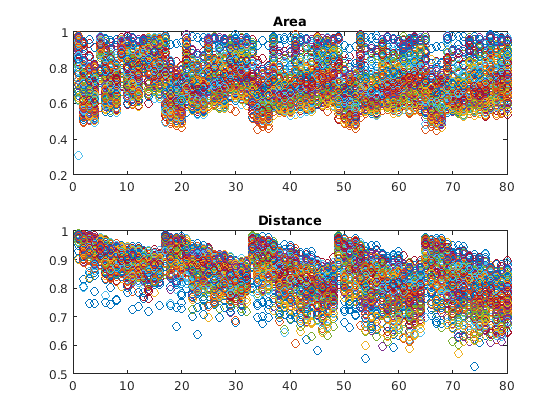

subplot(2,1,1)
plot(AreaMetric, 'o')
title('Area')
subplot(2,1,2)
plot(DistanceMetric, 'o')
title('Distance')

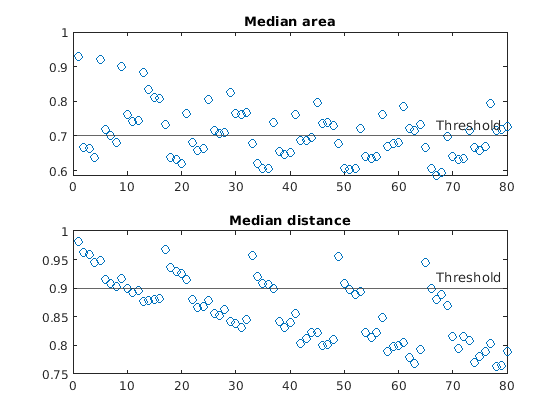

close all
MedianDistance = median(DistanceMetric');
MedianArea = median(AreaMetric');
TresArea = 0.7;
TresDist = 0.9;

subplot(2,1,1)
plot(MedianArea, 'o')
hold on
yline(TresArea,'-','Threshold');
title('Median area')

subplot(2,1,2)
plot(MedianDistance, 'o')
hold on
yline(TresDist,'-','Threshold');
title('Median distance')

## Best Parameter Combination

AreaPoints = find(MedianArea >= TresArea);
DistancePoints = find(MedianDistance >= TresDist);

sum(ismember(AreaPoints, DistancePoints))

ans = 7

Kruskal-Wallis Test

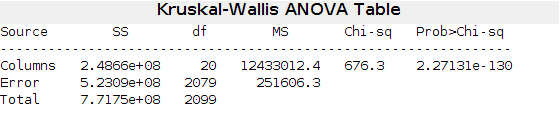

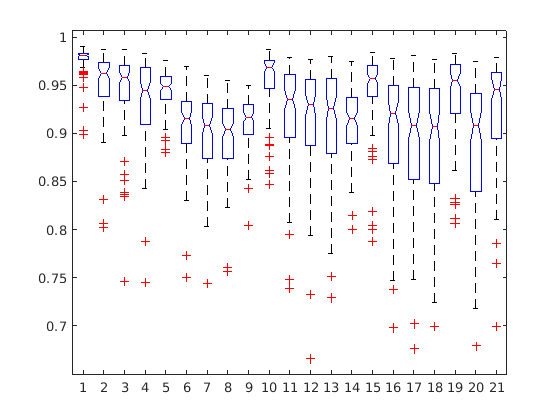

SelectedDistance = DistanceMetric(DistancePoints,:)';
p = kruskalwallis(SelectedDistance);

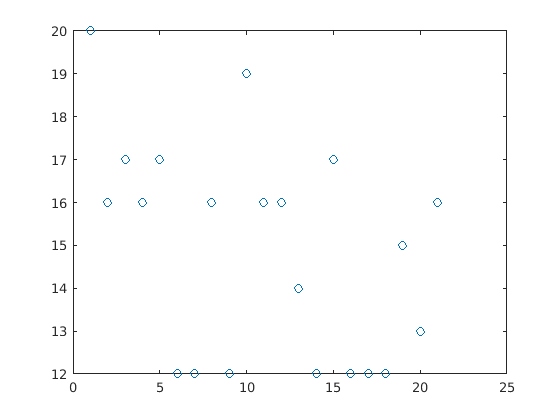

N = length(DistancePoints);
RankSumTestP = zeros(N,N);
RankSumTestBool = zeros(N,N);

for i = 1 : N
    for j = 1 : N
        RankSumTestP(i, j) = ranksum(SelectedDistance(:, i), SelectedDistance(:, j));
        %null hypothesis: data in x and y are samples from continuous distributions with equal medians
        if RankSumTestP(i, j) <= 0.05 %reject null (?)
            RankSumTestBool(i, j) = 1;
        end
    end
end

[Max, idx] = max(mean(SelectedDistance));
Comparation = sum(RankSumTestBool');
plot(Comparation, 'o')

[~, indexBest] = sort(Comparation, 'descend');
for i = 1 : 3
    j = DistancePoints(indexBest(i));
    disp(" ")
    disp("alpha:" + alpExp(j))
    disp("Samples:" + SampExp(j))
    disp("Occupation:" + OccupExp(j))
end

alpha:0


Samples:10


Occupation:0.1


alpha:0.25


Samples:10


Occupation:0.1


alpha:0


Samples:100


Occupation:0.1


## Worst parameter combination

AreaPoints = find(MedianArea < TresArea);
DistancePoints = find(MedianDistance < TresDist);

sum(ismember(AreaPoints, DistancePoints))

ans = 27

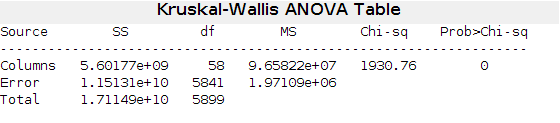

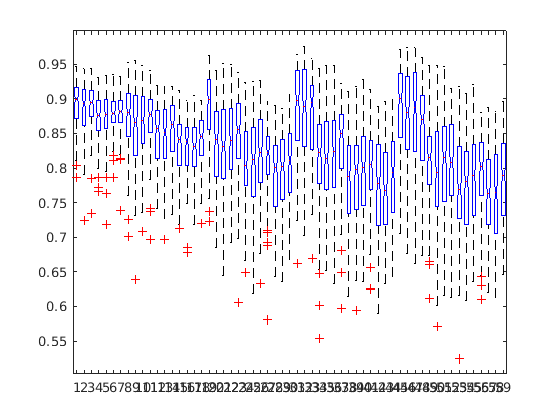

SelectedDistance = DistanceMetric(DistancePoints,:)';
p = kruskalwallis(SelectedDistance);

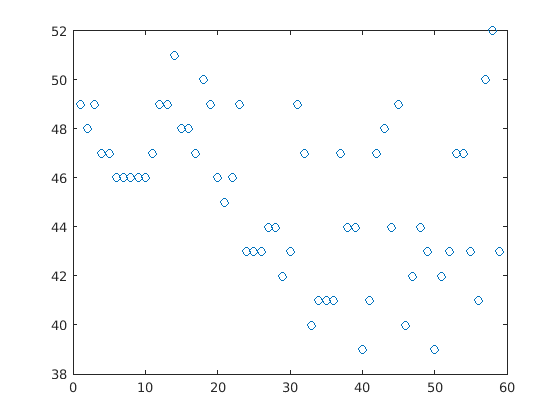

N = length(DistancePoints);
RankSumTestP = zeros(N,N);
RankSumTestBool = zeros(N,N);

for i = 1 : N
    for j = 1 : N
        RankSumTestP(i, j) = ranksum(SelectedDistance(:, i), SelectedDistance(:, j));
        %null hypothesis: data in x and y are samples from continuous distributions with equal medians
        if RankSumTestP(i, j) <= 0.05 %reject null (?)
            RankSumTestBool(i, j) = 1;
        end
    end
end

[Max, idx] = max(mean(SelectedDistance));
Comparation = sum(RankSumTestBool');
plot(Comparation, 'o')

[~, indexBest] = sort(Comparation, 'descend');
for i = 1 : 3
    j = DistancePoints(indexBest(i));
    disp(" ")
    disp("alpha:" + alpExp(j))
    disp("Samples:" + SampExp(j))
    disp("Occupation:" + OccupExp(j))
end

alpha:1


Samples:100


Occupation:0.7


alpha:0.25


Samples:1000


Occupation:0.5


alpha:0.25


Samples:1000


Occupation:0.7


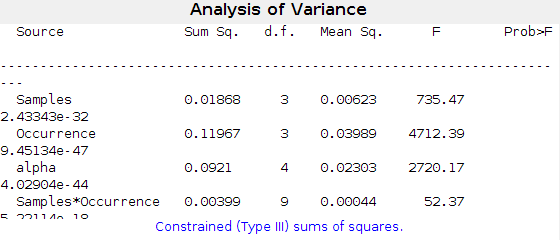

[~,~,stats] = anovan(mean(DistanceMetric, 2),{SampExp, OccupExp, alpExp},'model','interaction','varnames',{'Samples','Occupation','alpha'});

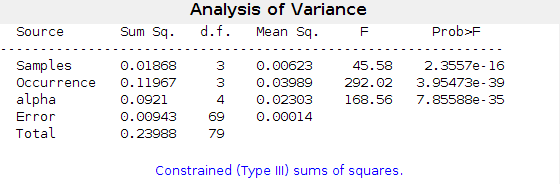

[~,~,stats] = anovan(mean(DistanceMetric, 2),{SampExp, OccupExp, alpExp},'model','linear','varnames',{'Samples','Occupation','alpha'});

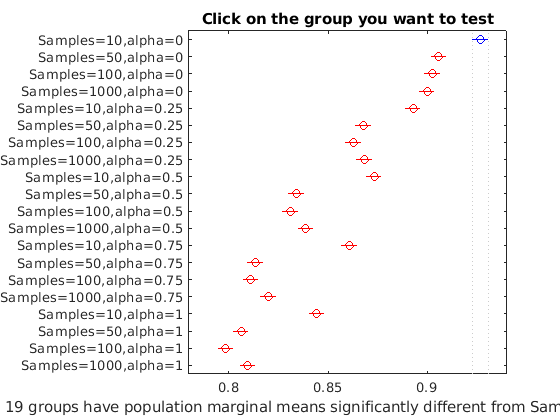

results = multcompare(stats,'Dimension',[1 3]);